# Extracting Trial Represenative Saccade Patterns

This script will demonstrate the workings of an algorithm leveraging tools from network science to extract a ***trial representative saccade pattern (TRSP)*** from a series of chronologically performed saccades. The extracted TRSP is meant to represent a cyclic pattern of saccades which was performed the most during a task specific trial. 

First, it is necessary to generate some random saccade data.

numb_saccades = 30; % Recommended to not go beyond a value of 30 to ensure quick performance
numb_trials = 1;
[trial_saccade_data] = constructExample_saccadeData(numb_saccades, numb_trials);

Visualize the generated saccade data of one trial. Green dot idicates starting target and red indicates end target.

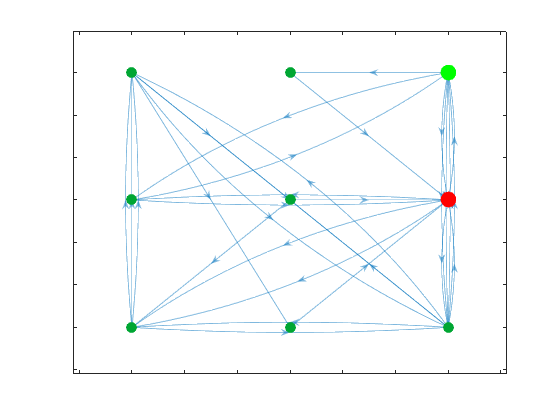

drawSaccadeSeq(trial_saccade_data(:,:,1)); 

With the data in the proper format, it is now possible to extract the trial representative saccade pattern from the above trial. 

The extraction starts by conversion of the saccade sequence into a saccade network, which is represented computationally as a 9x9 adjacency matrix. Each node in the network corresponds to one of the green targets in the task. An edge between two nodes exist if a saccade is observed in the data between those two targets. Furthermore, the weight of the edge is defined as the number of times a saccade between those two targets occurs. 

% Convert the trial sequence of saccades into a saccade adjacency matrix 
[saccade_matrix] = convertSeqToMatrix(trial_saccade_data(:,:,1));

% Identify the TRSP
[trsp_sequence] = identifyTRSP(saccade_matrix);

Visualize the extracted TRSP. Only a red dot is shown as the each TRSP is loop (start and end node are the same).

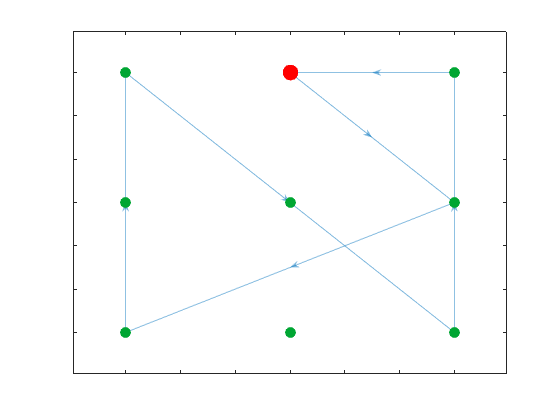

drawSaccadeSeq(trsp_sequence);

# Conversion of TRSP into 1-D Waveform 

The TRSP can be converted into a 1-D representation called the saccade waveform which enables for more robust and simplified comparison between TRSPs. This is done by treating the TRSP as a polygon consisting of a set of (x, y) coordinates. The centroid of the polygon is found, and the saccade waveform is created by calculating the Euclidean Distance between the centroid and all the coordinate points of the polygon.

First the identified TRSP sequence (see above section) must be converted into a polygon representation. 

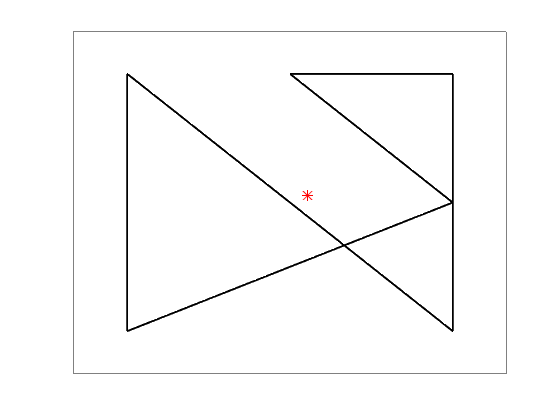

% Convert saccade sequence to polygon
[trsp_polygon] = saccadeToPolygon(trsp_sequence);

% Find the polygon centroid
poly_centroid = [mean(trsp_polygon(:,1)), mean(trsp_polygon(:,2))];

% Plot polygon representation and centroid (red star)
figure;
plot(trsp_polygon(:,1), trsp_polygon(:,2), 'Color', 'black' , 'LineWidth', 2); 
hold on 
plot(poly_centroid(1), poly_centroid(2), 'r*', 'MarkerSize', 10)
box on
xlim([0,8]);
ylim([0,8]); 
set(gca, 'xtick', [], 'xticklabel', [],...
    'ytick', [], 'yticklabel', [],...
    'XColor', [0.5,0.5,0.5], 'YColor', [0.5,0.5,0.5],'LineWidth', 1);

The polygon representation is now converted into a 1-D waveform.

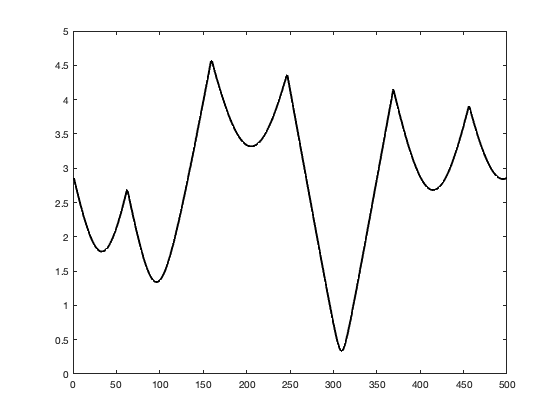

% Convert polygon to saccade waveform
[trsp_waveform] = polygonToWaveform(trsp_polygon, poly_centroid);


% Plot waveform representation
figure;
plot(trsp_waveform, 'Color', 'black', 'LineWidth', 2)

In this form, it is possible to represent any rotation of the original 2D polygon by performing a circular shift to the derived waveform. A circular shift is a mathematicaloperation where a vector is rearranged such that the last element is moved to the first position and all other elements are shifted forward by one. By performing this operation `l `times, it is possible to shift the last `l` values to the front of the vector and all other values forward by `l` positions.

% How many degrees is the original poloygon rotated if l consecutive
% circular shifts occur
numb_shift = 2;
numb_deg = 360*numb_shift/500;
disp(['Number of circular shifts performed: ' num2str(numb_shift)]); disp(['Equivalent to rotation by: ' num2str(numb_deg) char(176)])

Number of circular shifts performed: 2
Equivalent to rotation by: 1.44°


The below graphic displays rotation of the original TRSP polygon side-by-side of a constant circular shift. In the waveform subplot, the RED indicates the original waveform, and the BLACK indicates the shifted versions. 

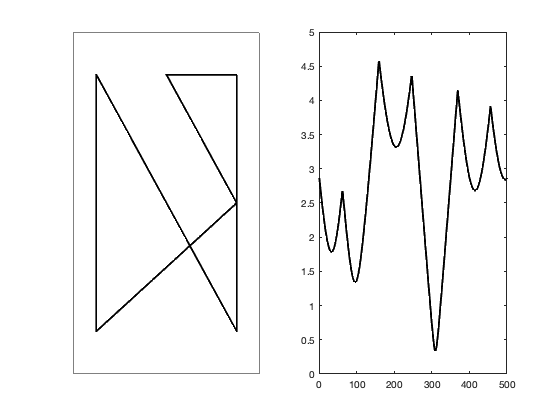

% Settings necessary to allow for live animations in script
s = settings;
s.matlab.editor.AllowFigureAnimation.PersonalValue = true;

% Run animation of polygon rotation & waveform shifting
degree_step = 2; % Sets rotation degree increments
polygonRotation_withShift(trsp_polygon, poly_centroid, degree_step);

# Comparison of Multiple TRSPs

Converting each TRSP into a saccade waveform enables a simple method for comparing individual TRSPs. In this case, the Euclidean distance between two waveforms is used as a similarity metric. Furthermore, by comparing one waveform to all possible circular shifts of another waveform and finding the minimum distance the similarity metric becomes orientation independent. Below is an example of how a comparison between 10 TRSPs would be performed.

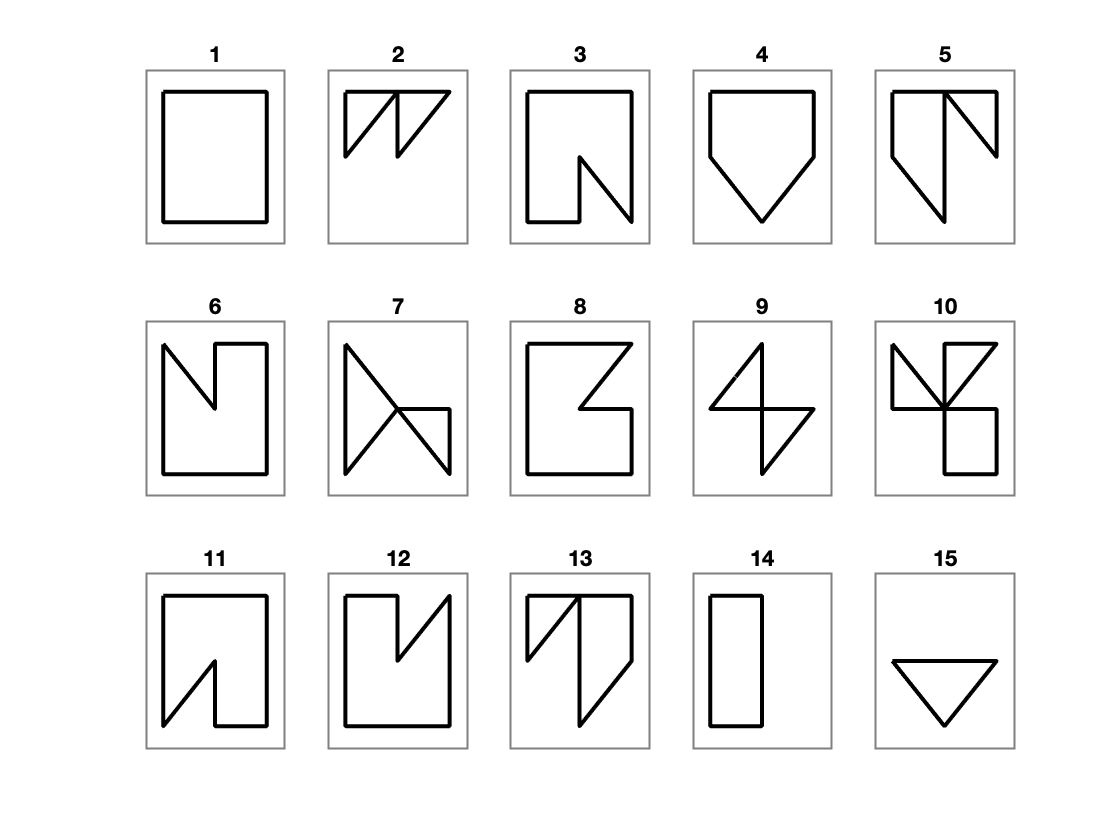

% Load in a set of 10 pre-defined TRSPs each in the form of a Sx2 matrix
% contained in one cell-array
load("example_trsp_sequences.mat");

% Stores TRSP polygon data
trsp_polygon_set = cell(1,size(example_trsp_sequences,2));

% Stores TRSP waveform data
trsp_waveform_mat = zeros(size(example_trsp_sequences,2),600);

% Visualize all TRSPs
figure;
for t = 1:size(example_trsp_sequences,2)
    % Convert to polygon
    [trsp_polygon_set{t}] = saccadeToPolygon(example_trsp_sequences{t});
 
    % Find the polygon centroid
    poly_centroid(t,:) = [mean(trsp_polygon_set{t}(:,1)), mean(trsp_polygon_set{t}(:,2))];
    
    % Convert to waveforms
    trsp_waveform_mat(t,:) = polygonToWaveform(trsp_polygon_set{t}, poly_centroid(t,:));
    
    % Plot polygon in subplot
    subplot(3,5,t)
    plot(trsp_polygon_set{t}(:,1), trsp_polygon_set{t}(:,2), 'Color', 'black' , 'LineWidth', 2); 
    title(num2str(t))
    xlim([0,8]);
    ylim([0,8]); 
    set(gca, 'xtick', [], 'xticklabel', [],...
        'ytick', [], 'yticklabel', [],...
        'XColor', [0.5,0.5,0.5], 'YColor', [0.5,0.5,0.5],'LineWidth', 1);
end

Now the waveform data needs to be formatted so as to allow for rotation independent comparison of TRSPs. 

First, it is necessary to perform a `cn` number of circular shifts on each waveform and its equivalent mirror-image in increments of `l`and store each othe shifted waveform versions with the original. In this case, the below code creates a (`cn+1)` x 600 x 15 matrix where `cn = 60 `circular shifts were created at an increment of `l = 10 `(which corresponds to rotations of ~6 degrees).

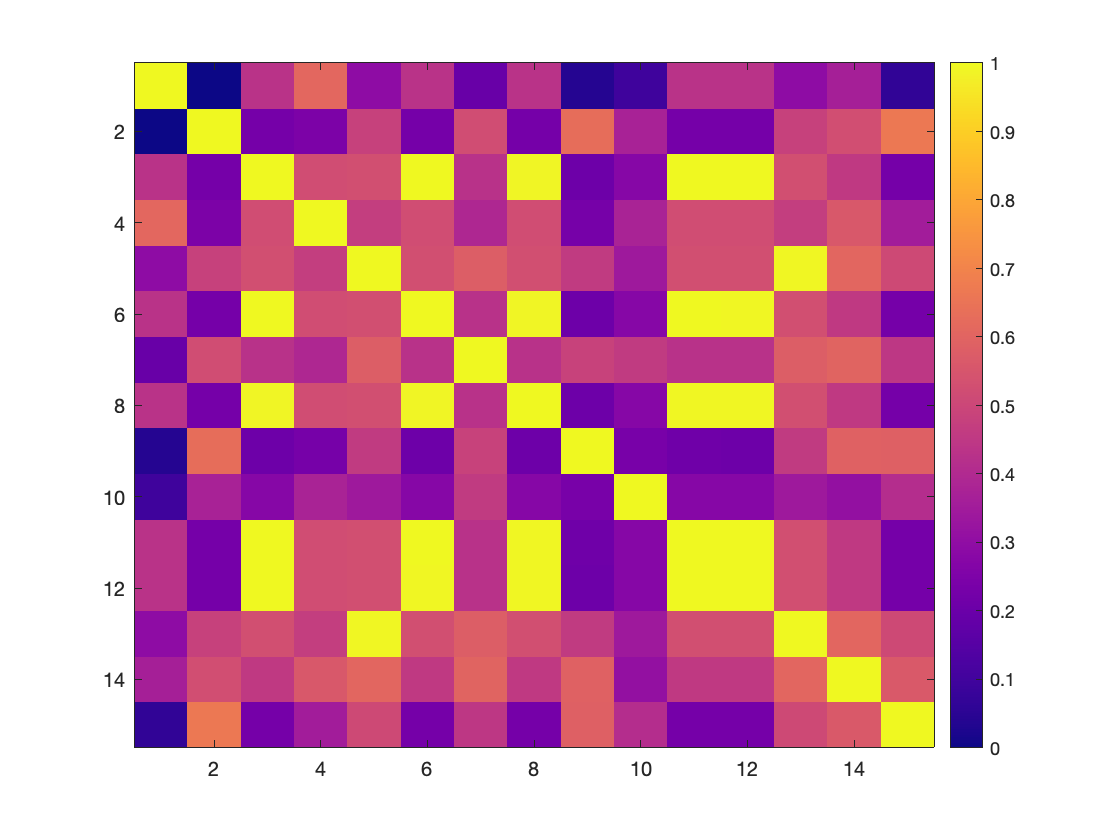

% Creates a (cn+1)x600x10 matrix
for trsp = 1:15
    shifted_data(:,:,trsp) = circularShift(trsp_waveform_mat(trsp,:), 6);
end

% Create similarity metric matrix
[waveform_distance_matrix] = compareWaveforms(trsp_waveform_mat, shifted_data, 0);
waveform_distance_matrix = triu(waveform_distance_matrix) + triu(waveform_distance_matrix)';


% Convert euclidean distance (which looks at dissimilarity) to a true
% measure of similarity
waveform_distance_matrix = ones(size(waveform_distance_matrix)) - waveform_distance_matrix./max(max(waveform_distance_matrix));



% Visualize similarity
figure;
imagesc(waveform_distance_matrix); 
colormap 'plasma';
colorbar; 